clear all; clc; close all
%  part1: plot the waveforms for different conditions

%   1	2	3	4	5	6	7	8	9	10	11	12	13	14	15	16	17	18	19	20	21	22	23	24	25	26	27	28	29	30	31	32	33	34	35	36	37	38	39	40	41	42	43	44	45	46	47	48	49	50	51	52	53	54	55	56	57	58	59	60	61	62
%   FP1	FPZ	FP2	AF3	AF4	F7	F5	F3	F1	FZ	F2  F4	F6	F8	FT7	FC5	FC3	FC1	FCZ	FC2	FC4	FC6	FT8	T7	C5	C3	C1	CZ	C2	C4	C6	T8	TP7	CP5	CP3	CP1	CPZ	CP2	CP4	CP6	TP8	P7	P5	P3	P1	PZ	P2	P4	P6	P8	PO7	PO5	PO3	POZ	PO4	PO6	PO8	O1	OZ	O2	M1	M2

%定义被试的编号
b = 5; base = -0.6; erp = 1.4;  %b为被试数量，base为基线时间，erp为时间相关电位触发时间，后两者单位为s；
w = 32; ww = 52; ls= 250; lsl = 300;
k = ls-base+1; kk = ls-base+1+lsl; 
% w代表所需要处理的第一个电极，ww代表最后一个；ls代表所需要的时间段的起始点，lsl代表所需的时间段长度。
%Subj = [1:b]; %% subject number
%定义marker信息
%Cond = {'1','2'}; %% condition name
Cond = {'100','200'};
%定义数据所在的路径
setpath = 'I:\chineseversion\real\1';  %定义路径

for i = [1:b];
    %拼接当前被试的文件名
     setname = strcat(num2str(i),'.set'); %% name of the set file
     %setname = strcat('1.set');
     %定义数据所在的路径
     %setpath = 'D:\0_WMR\30EEG_day2\Example_data\';%% filepath of the set file
     %导入该被试的数据
     EEG = pop_loadset('filename',setname,'filepath',setpath);   %% load the data into EEG
     EEG = eeg_checkset( EEG );
     %对于每一个条件
    for j = 1:length(Cond)
        %以对这个条件进行分段的方式 提取这个条件的所有trail
        %将结果赋值给EEG_new 以防数据覆盖
        EEG_new = pop_epoch( EEG, Cond(j), [base  erp], 'newname', 'Merged datasets pruned with ICA', 'epochinfo', 'yes'); %% epoch by conditions, input to EEG_new
        EEG_new = eeg_checkset( EEG_new );
        %对分好段的数据进行基线校正
        EEG_new = pop_rmbase( EEG_new, [1000*base  0]); %% baseline correction for EEG_new
        EEG_new = eeg_checkset( EEG_new );
        %EEG_new.data ch*times * trails
        %对每个条件进行个体水平的叠加平均
        %沿着第三个维度 即trail维度进行平均 --> ch * times * 1
        %挤压多余的维度 --》 ch * times
        %将第i个被试 第j个条件 个体水平叠加平均好的数据 汇总到EEG_avg中
        %EEG_avg 4D sub * cond * ch * times
        EEG_avg(i,j,:,:) = squeeze(mean(EEG_new.data,3));  %% average across trials for EEG_new, EEG_avg dimension: subj*cond*channel*time
    end
end

pop_loadset(): loading file I:\chineseversion\real\1\1.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():30 epochs selected
Epoching...
pop_epoch():28 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():110 epochs selected
Epoching...
pop_epoch():107 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file I:\chineseversion\real\1\2.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():30 epochs selected
Epoching...
pop_epoch():28 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():110 epochs selected
Epoching...
pop_epoch():103 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file I:\chineseversion\real\1\3.set ...


pop_epoch():20 epochs selected
Epoching...
pop_epoch():20 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():88 epochs selected
Epoching...
pop_epoch():88 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_loadset(): loading file I:\chineseversion\real\1\4.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():26 epochs selected
Epoching...
pop_epoch():26 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():106 epochs selected
Epoching...
pop_epoch():106 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file I:\chineseversion\real\1\5.set ...


pop_epoch():28 epochs selected
Epoching...
pop_epoch():28 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():105 epochs selected
Epoching...
pop_epoch():105 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...



    for elect = [w:ww]; %定义几个要看的电极  
    ele = elect - w + 1; %这里的数字改一下即可保存到不同的表格
    for ig = [1:b];
       %EEG_avg_aft1 = EEG_avg(i,2,:,:) - EEG_avg(i,1,:,:);
       %EEG_avg_aft1 = squeeze(mean(EEG_avg_aft1,2));
        EEG_avg_100(ig,:) = squeeze(EEG_avg(ig,1,elect,k:kk)); %得到刺激后250-550范围内偏差刺激所有值
        EEG_avg_200(ig,:) = squeeze(EEG_avg(ig,2,elect,k:kk)); %得到刺激后250-550范围内标准刺激所有值
        EEG_avg_100_max(ig,:) = max(EEG_avg_100(ig,:));  %计算偏差刺激在250到550范围内的最大值
        %EEG_avg_200_max(i,:) = max(EEG_avg_200(i,:)); 
        ii = EEG_avg_100_max(ig,:);
        %iii = EEG_avg_200_max(i,1)
        EEG_avg_100_qianfu(ig,:) = find(EEG_avg_100(ig,:) == ii); %找到最大值所对应的时间点，这个时间点是250-550范围内的点
        iii = EEG_avg_100_qianfu(ig,:); 
        %EEG_avg_200_qianfu(i,:) = find(EEG_avg_200(i,:) == iii); %这一步没什么用
        EEG_avg_200_max(ig,:) = EEG_avg_200(ig,iii); %找到偏差刺激峰值时，标准刺激所对应的峰值
        EEG_avg_qianfuqi = EEG_avg_100_qianfu + (k+base*1000-1); %转化为标准时间点
        %EEG_avg_100_qianfu(i,:) = EEG_avg_200_qian(i,);
        %aa = length(ww);
    %end
        EEG_sub = EEG_avg_100_max - EEG_avg_200_max;
    end 
%         xlswrite('H:\zhongxinketi_chinese\result.xlsx', EEG_avg_100_max', ele, 'A1')
%         xlswrite('H:\zhongxinketi_chinese\result.xlsx', EEG_avg_200_max', ele, 'A2')
%         xlswrite('H:\zhongxinketi_chinese\result.xlsx', EEG_avg_qianfuqi', ele, 'A3')
%         xlswrite('H:\zhongxinketi_chinese\result.xlsx', EEG_sub', ele, 'A4')
        %第一行是偏差刺激的最大值，第三行是潜伏期，第二行是在潜伏期的时间点下标准刺激的值，第四行是潜伏期的时间点下偏差刺激和标准刺激的差值
    end 

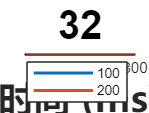

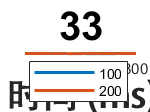

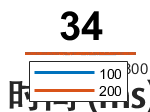

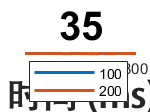

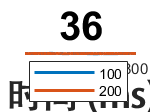

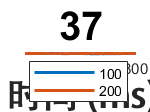

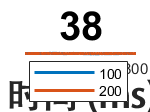

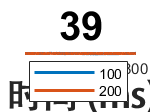

t1 = -200; t2 = 800; r1 = -15; r2 = 15;
    %定义感兴趣的电极
for Cz = [w:ww]; %% channel to display
%EEG_avg sub * cond * ch * times
%提取所有被试 所有条件 Cz电极 所有时间的数据 --> sub * cond * 1 * times
%沿着第一个维度做平均 被试的维度 --> 组水平平均 --> 1 * cond * 1 * times
%挤压多余的维度  --> 2D cond * times
mean_data = squeeze(mean(EEG_avg(:,:,Cz,:),1)); %% select data at Cz, and average across subjects, mean_data: cond*times
%subtr = EEG_avg(2,Cz,:)-EEG_avg(1,Cz,:);
%mean_data(3,:) = subtr;
%生成一个空画布
figure; 
%绘制4个条件的组水平波形图
plot(EEG.times, mean_data,'linewidth', 1.5); %% plot waveforms for different conditions
% plot(EEG.times, mean_data2,'linewidth', 1.5); 
%翻转纵轴
set(gca,'YDir','reverse');  %% reverse Y axis
%定义横纵轴的范围
axis([t1 t2 r1 r2]);  %% define the region to display
title(num2str(Cz),'FontWeight','bold','FontSize',20,'FontName','Arial'); 
xlabel('时间 (ms)','FontWeight','bold','fontsize',18,'FontName','Adobe 黑体 Std R');
xlabel('时间 (ms)','FontWeight','bold','fontsize',18,'FontName','Adobe 黑体 Std R');
%给图片加图例
legend(Cond)
end

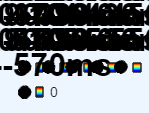

ts = 20; sr1 = -10; sr2 = 10;  %ts是每多长时间画一个图，sr是画图的深度参考值
EEG_avg_scaple = squeeze(EEG_avg(:,1,:,:));
time_interval = [ls:ts:ls+lsl]; %% specify the time intervals to display (to be changed)
%生成一个空画布
figure; 
%对于每个时间点
for iii = 1:length(time_interval) 
    %根据时间点的信息 定义感兴趣的时间范围 0 - 100 100 -200 etc
    latency_range = [time_interval(iii) time_interval(iii)+ts]; %% lower and upper limits
    %找到感兴趣的时间范围内的采样点的位置信息
    latency_idx = find((EEG.times>=latency_range(1))&(EEG.times<=latency_range(2))); %% interval of the specific regions
   %EEG_avg sub * ch * times
   %提取所有被试 所有通道 感兴趣时间范围内的数据--》 sub * ch *t1
   %沿着第一个维度 被试维度求平均 --》组水平平均 1*ch * t1
   %沿着第三个维度求平均 时间维度 制作平均地形图 --》 1 * ch * 1
   %挤压多余维度  1D ch
    Amplitude = squeeze(mean(mean(EEG_avg_scaple(:,:,latency_idx),1),3)); %% 1*channel (averaged across subjects and interval)
    aa = floor(lsl/ts);
    af = floor(sqrt(aa)); au = ceil(sqrt(aa));
    %绘制au行af列的六张图
    subplot(af+1,au+1,iii); 
    topoplot(Amplitude,EEG.chanlocs,'maplimits',[sr1 sr2]); %% topoplot(Amplitude,EEG.chanlocs);
    %将感兴趣的时间的数字转化为字符并进行拼接
    setname = strcat(num2str(latency_range(1)),'--',num2str(latency_range(2)),'ms'); %% specify the name of subplots
    title(setname,'fontsize',16,'FontName','Arial'); %% display the names of subplots
    colorbar;
end